# Comparing parameters between conditions

Comparing data across conditions, independently fit models for each condition and then look at how the parameters differ. 

the function **SplitDataByCondition()** takes a data struct with a condition field as input, and returns a cell array of data structs, one per condition. 

clear all;
% Splitting a dataset by condition
data.errors = [-89, 29, -2, 6, -16, 65, 43, -12, 10, 0, 178, -42, 52, 1];
data.condition = [1 1 1 1 1 1 1 2 2 2 2 2 2 2];
[datasets, conditionOrder] = SplitDataByCondition(data);

conditionOrder

conditionOrder =      1     2


% Structure of datasets{1}  
datasets{1}

ans = struct with fields:
       errors: [-89 29 -2 6 -16 65 43]
    condition: [1 1 1 1 1 1 1]


% Structure of datasets{2}
datasets{2}

ans = struct with fields:
       errors: [-12 10 0 178 -42 52 1]
    condition: [2 2 2 2 2 2 2]


% You can then loop over these datasets, fitting each separately.
% SplitDataByField is the more general version of SplitDataByCondition,
% rather than call SplitDataByCondition, u could also call
% SplitDataByField:

% [datasets, conditionOrder] = SplitDataByField(data, 'condition');

% give you equivalent results (and also allow you to split by n or any
% other dimension of your data).

% for i=1:length(datasets)
% posteriorSamples{i} = MCMC(datasets{i}, StandardMixtureModel);
% end


## Compare full posterior distribution between conditions

Compare not only the best fit parameters for each model, but  also the full posterior distributions. 

To do this, you can make use of the  PlotPosteriorComparison() function, which plots two posterior distributions: 

>>**PlotPosteriorComparison(posteriorSamples, model.paramNames) **

if we apply data with **200 trials where condition 1 has from g=0.1 and sd=20**, whereas **condition 2 has g=0.3, sd=30**

clear data;
model = StandardMixtureModel();
% SampleFromModel() takes as input a model and the parameters of that
% model, and generates data from this model.
data.errors(1:200) = SampleFromModel(model, [0.1, 20], [1 200]);
data.errors(201:400) = SampleFromModel(model, [0.3, 30], [1 200]);
data.condition(1:200) = 1;
data.condition(201:400) = 2;

[datasets, conditionOrder] = SplitDataByCondition(data);
% split up the datasets and fit them independently
for i=1:length(datasets)
  posteriorSamples{i} = MCMC(datasets{i}, StandardMixtureModel);
end


   Running 3 chains...
   ... not yet converged (200); btw/within variance: 2.89
   ... not yet converged (400); btw/within variance: 1.47
   ... not yet converged (600); btw/within variance: 1.29
   ... chains converged after 800 samples!
   ... collecting 6000 samples from converged distribution

   Running 3 chains...
   ... not yet converged (200); btw/within variance: 2.07
   ... chains converged after 400 samples!
   ... collecting 6000 samples from converged distribution


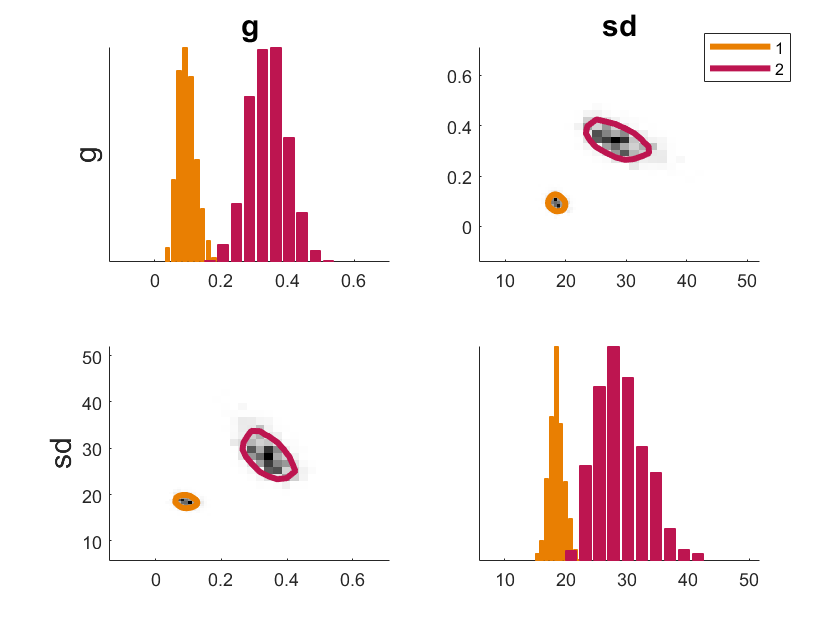

ans =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [1 1 1]
    Position: [440 438 560 420]
       Units: 'pixels'

  Show all properties



% compare not only the best fit parameters for each model, but also the
% full posterior distributions： 
PlotPosteriorComparison(posteriorSamples, model.paramNames)

## compare many subjects’ best-fit parameter values between conditions

If wish to compare many subjects’ best-fit parameter values for different conditions. 

The MemToolbox includes one function designed for **visualizing how parameter values differ between different conditions**. e.g. imagine calculated MAP parameters for 2 conditions for a set of 8 subjects:

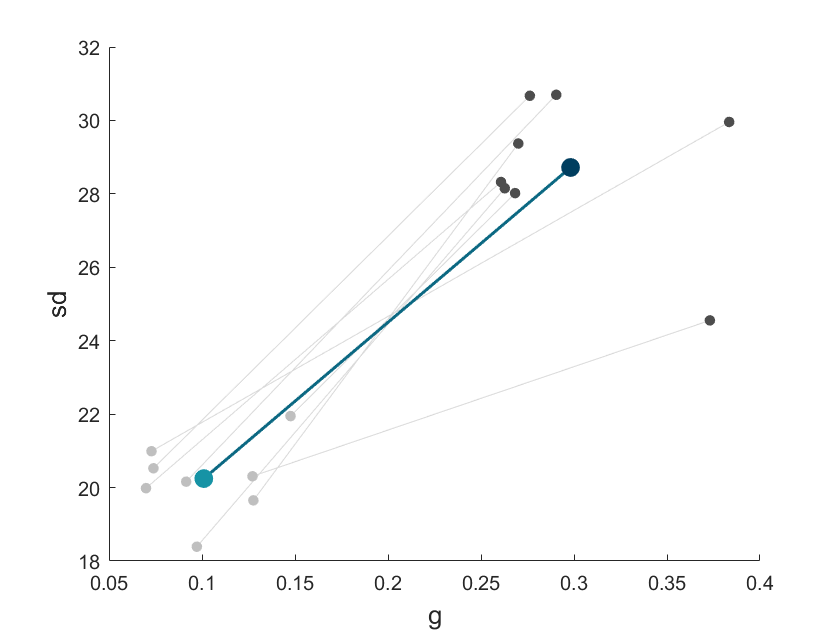

clear data;

for sub=1:8
  data{sub}.errors(1:200) = SampleFromModel(model, [0.1, 20], [1 200]);
  data{sub}.errors(201:400) = SampleFromModel(model, [0.3, 30], [1 200]);
  data{sub}.condition(1:200) = 1;
  data{sub}.condition(201:400) = 2;
end

for sub=1:8
  [datasets, conditionOrder] = SplitDataByCondition(data{sub});
  for cond=1:length(datasets)
    params{cond}(sub,:) = MAP(datasets{cond}, model);
  end
end

% visualize how the g and sd parameters differ between these conditions.
% the PlotShift function shows you how the best fit parameters for g and sd
% differ between conditions using lines drawn between subjects’ points from 
% the two conditions:

PlotShift(params{1}, params{2}, model.paramNames);

The light gray dots show the parameter values for each subject in condition 1; the dark gray dots show the parameter values for each subject in condition 2. The blue dots show the means per condition. Lines connect points that derive from the same subjects. 

This visualization uses a format much like that used by PlotPosterior and PlotPosteriorComparison to see how parameter values compare across subjects. This allows you to examine **whether the parameters are correlated with each other within a condition**, and how the **variance across conditions relates to the variance within a condition.**